# von Karman beam

## Initialize

Include the function folder.

addpath(genpath(fullfile('..', 'LSM-opt-functions')))

## Preliminary analysis

Define the type of the system.

sysArgs.systemType = @SystemYetAnotherFEcode;
sysArgs.yafec_assembly_constructor = @define_beam_model;

Define system parameters.

h = 0.01;
L = 1;
p = [0, 0, h, L];

Build assembly.

sys = feval(sysArgs.systemType, p, sysArgs);

Initial eigenvalue analysis to identify the shape of the first mode.

sys = sys.modal_analysis();
sysArgs.phiRef = sys.phi(:, 1);

Assign the master mode.

sys.omega0 = sys.omega(1);
sys.phi0 = sys.phi(:, 1);

Define the target dof as the vertical displacement of the middle node.

iDofMiddle = (sys.myAssembly.Mesh.nElements / 2) * 3 + 2;

Define the LSM arguments, i.e., the target dof of the system and the LSM expansion order.

lsmArgs.iDof = iDofMiddle;
lsmArgs.order = 3;
lsmArgs.orderMax = 11;

## Optimization problem

The objective function and the nonlinear constraints are defined in the `run_fmincon` function in this folder. 

Define the target points as frequency - amplitude pairs.

optArgs.omegaTarget = [1, 0.95] * sys.omega0;
optArgs.zTarget = [0.2, 0.4] * h;

Specify if the frequency - amplitude pairs are treated as equality constraint (0), upper inequality constraint (1), or lower inequality constraint (-1).

optArgs.coeffTarget = [0, 0];

Define the initial conditions for the design variables.

x0 = p;

Define the lower and upper bounds for the design variables.

xl = [  0,   0, h/10, 0.5];
xu = [2*h, 2*h, 10*h, 1.5];

Define the linear equality and inequality constraints (if any).

A = []; b = [];
Aeq = []; beq = [];

## Optimizer options

In this work, `fmincon` is used to solve the nonlinear optimization problem.

Define below the required options.

options = optimoptions('fmincon', 'Display', 'iter');
options.Algorithm = "interior-point";
options.EnableFeasibilityMode = true;
options.SpecifyObjectiveGradient = true;
options.SpecifyConstraintGradient = true;
options.ConstraintTolerance = 1e-3;
options.StepTolerance = 1e-3;

## Solve the optimization problem

Solve the optimization problem.

Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

Iter 0: 0.009       0.009        0.01           1 - res: 0.0097548
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    9.000000e-03    4.177e+01    1.273e-01
    1       4    7.294362e-03    3.953e+01    1.083e+00    4.369e-02
Iter 1: 0.011736   0.0069899   0.0096455      1.0436 - res: 0.012321
    2       5    4.344407e-05    2.424e+01    4.281e+00    1.996e-01


Iter 2: 0.013876   3.495e-05   0.0096335      1.2431 - res: 0.076853
    3       8    2.202689e-03    5.269e+00    2.803e+00    6.091e-02


Iter 3: 0.012186   0.0018632   0.0077095      1.1822 - res: 0.020592
    4       9    2.159150e-03    1.105e-01    2.768e+00    2.138e-02
Iter 4: 0.01186     0.00186   0.0077914      1.1608 - res: 0.0056109
    5      11    2.268131e-03    1.444e-02    3.494e+00    5.851e-02
Iter 5: 0.010833   0.0020576   0.0072724      1.1023 - res: 0.0045693
    6      13    2.221745e-03    5.748e-03    5.980e-01    1.285e-03
Iter 6: 0.010642   0.0020132   0.0074115      1.1036 - res: 0.0042891
Done: 0.010642   0.0020132   0.0074115      1.1036

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the <

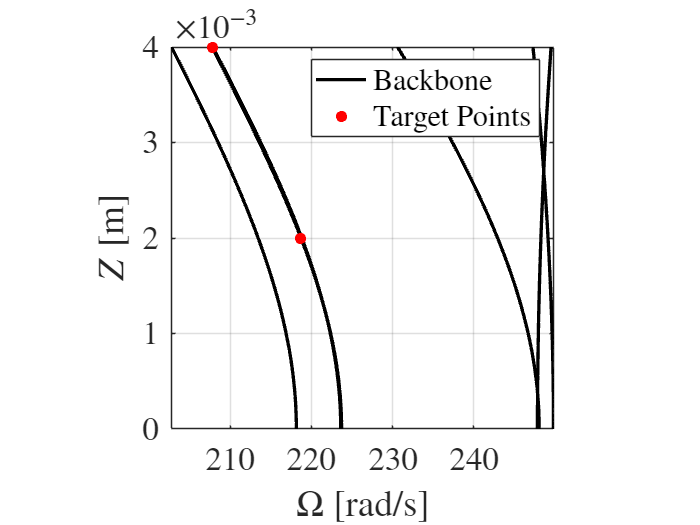

tStart = tic;
[x, orderNew] = run_fmincon(x0, A, b, Aeq, beq, xl, xu, sysArgs, lsmArgs, optArgs, options);

tElapsed = toc(tStart);
disp(['Elapsed time is ', num2str(tElapsed, '%.2f'), ' seconds.'])

Elapsed time is 671.89 seconds.


## Post processing

Build the system and perform the eigenvalue analysis.

sys = feval(sysArgs.systemType, x, sysArgs);
sys = sys.modal_analysis();

Identify the master mode using the modal assurance criterion.

modeIndex = modal_assurance_criterion(sys.phi, sysArgs.phiRef);
sys.omega0 = sys.omega(modeIndex);
sys.phi0 = sys.phi(:, modeIndex);
sys = sys.state_space_modal_analysis();

Build the LSM.

lsm = LSM(sys, orderNew);
lsm = lsm.compute_manifold();

Compute the backbone points.

rhoTarget = lsm.solve_rho(optArgs.zTarget, lsmArgs.iDof);
rho = linspace(0, max(rhoTarget), 51);
z = lsm.compute_z(rho, lsmArgs.iDof);
omega = lsm.compute_omega(rho);

Plot the backbone curve with the target points.

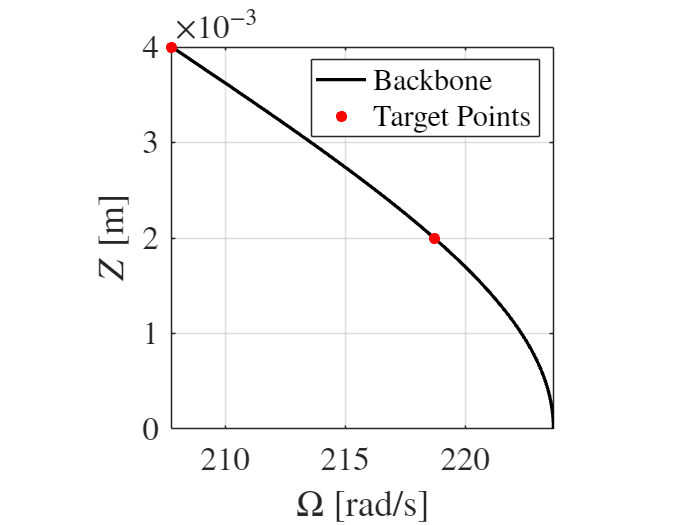

figure();
plot_backbone(omega, z, optArgs.omegaTarget, optArgs.zTarget);

Plot the optimal manifold.

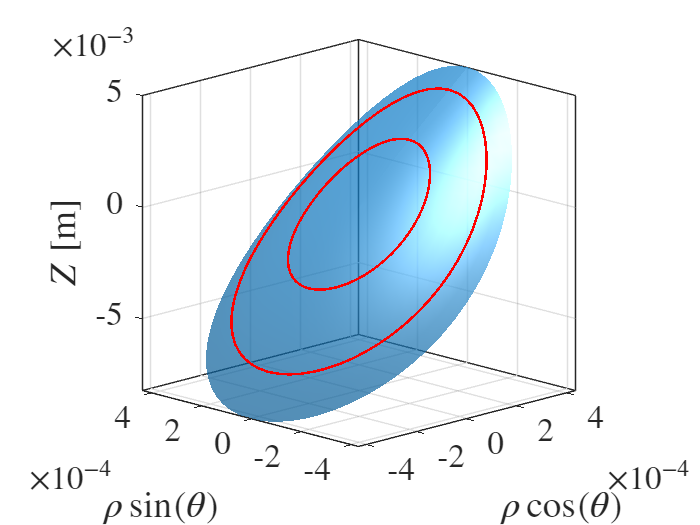

figure();
plot_manifold(lsm, rhoTarget, lsmArgs.iDof)
view(-45, 15)

Plot the optimal shape of the beam.

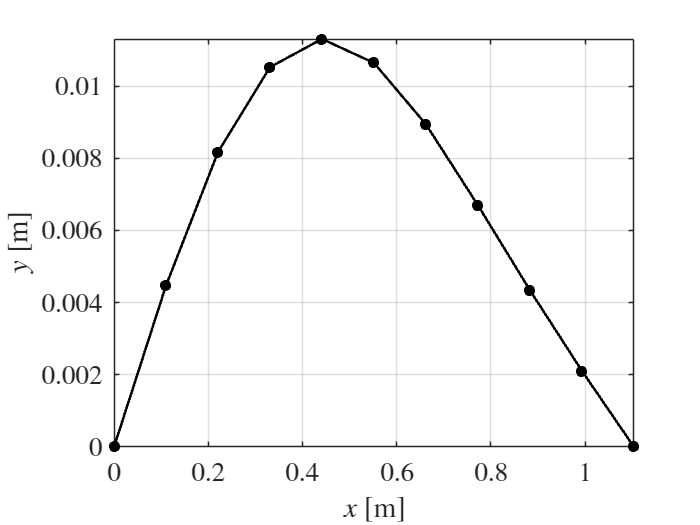

nodes = sys.myAssembly.Mesh.nodes;
figure();
hold on; grid on;
plot(nodes(:, 1), nodes(:, 2), 'k.-', 'LineWidth', 1.5, 'MarkerSize', 20)
xlabel('$x$ [m]', 'Interpreter', 'latex')
ylabel('$y$ [m]', 'Interpreter', 'latex')
axis tight
box on
set(gca, 'FontSize', 16, 'TickLabelInterpreter', 'latex')